# X2

clear all
dati=xlsread("Recording-27.xlsx");

## lavorazione


X_R1=dati(:,5)

X_R1 = 	1.0e+03 *

   -2.9739
   -2.9739
   -2.9739
   -2.9739
   -2.9739
   -2.9739
   -2.9739
   -2.9739
   -2.9734
   -2.9711


Y_R1=dati(:,6)

Y_R1 = 	1.0e+03 *

    1.6660
    1.6660
    1.6660
    1.6660
    1.6660
    1.6660
    1.6660
    1.6660
    1.6677
    1.6765


Z_R1=dati(:,7)

Z_R1 =   845.9443
  845.9443
  845.9443
  845.9443
  845.9443
  845.9443
  845.9443
  845.9443
  845.1319
  840.8204


X_R1=diff(X_R1)

X_R1 =          0
         0
         0
         0
         0
         0
         0
    0.4604
    2.3119
    3.8238


Y_R1=diff(Y_R1)

Y_R1 =          0
         0
         0
         0
         0
         0
         0
    1.6768
    8.8357
   16.5434


Z_R1=diff(Z_R1)

Z_R1 =          0
         0
         0
         0
         0
         0
         0
   -0.8124
   -4.3116
   -8.2121


v_R1=sqrt(X_R1.^2 +Y_R1.^2+ Z_R1.^2)./diff(dati(:,1))

v_R1 = 	1.0e+04 *

         0
         0
         0
         0
         0
         0
         0
    0.0080
    0.0421
    0.0786


index_nv=find(v_R1>7000);
dati_validi_vel=dati;

dati_validi_vel(index_nv,:)=[];
v_R1(index_nv)=[];
a_R1=diff(v_R1)./diff(dati_validi_vel(1:end-1,1))

a_R1 = 	1.0e+04 *

         0
         0
         0
         0
         0
         0
    0.0017
    1.4202
    1.5211
    1.5540


index_nv=find(a_R1>68000);
dati_validi_acc=dati_validi_vel;
dati_validi_acc(index_nv,:)=[];
a_R1(index_nv)=[];


X_R2=dati(:,9)

X_R2 = 	1.0e+03 *

   -0.9351
   -0.9351
   -0.9351
   -0.9351
   -0.9351
   -0.9351
   -0.9351
   -0.9351
   -0.9351
   -0.9351


Y_R2=dati(:,10)

Y_R2 = 	1.0e+03 *

    0.3891
    0.3891
    0.3891
    0.3891
    0.3891
    0.3891
    0.3891
    0.3891
    0.3891
    0.3891


Z_R2=dati(:,11)

Z_R2 = 	1.0e+03 *

    0.2695
    0.2695
    0.2695
    0.2695
    0.2695
    0.2695
    0.2695
    0.2695
    0.2695
    0.2695


X_R2=diff(X_R2)

X_R2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Y_R2=diff(Y_R2)

Y_R2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Z_R2=diff(Z_R2)

Z_R2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


v_R2=sqrt(X_R2.^2 +Y_R2.^2+ Z_R2.^2)./diff(dati(:,1))

v_R2 = 	1.0e+04 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


index_nv=find(v_R2>7000);
dati_validi_vel_R2=dati;

dati_validi_vel_R2(index_nv,:)=[];
v_R2(index_nv)=[];
a_R2=diff(v_R2)./diff(dati_validi_vel_R2(1:end-1,1))

a_R2 = 	1.0e+04 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


index_nv=find(a_R2>65000);
dati_validi_acc_R2=dati_validi_vel_R2;
dati_validi_acc_R2(index_nv,:)=[];
a_R2(index_nv)=[];

index_fine=find(dati_validi(:,1)>428 );
index_fine=index_fine(1)

index_fine = 6382

index_regime=find(dati_validi(:,1)>210 );
index_regime=index_regime(1)

index_regime = 3242

dati_regime=dati_validi(1:index_regime,:);


## plot

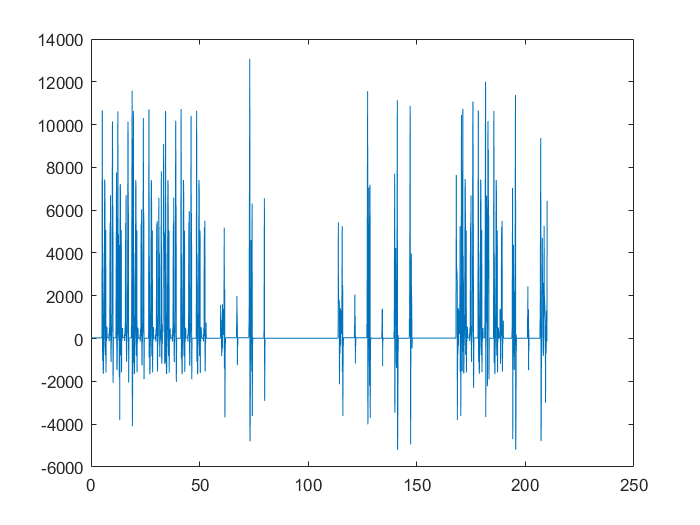

plot(dati_regime(:,1),dati_regime(:,3))

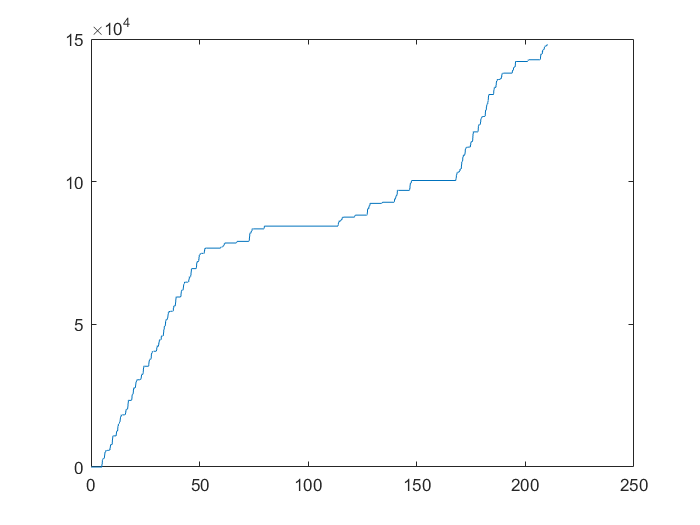

plot(dati_regime(:,1),dati_regime(:,2)-dati_regime(1,2))

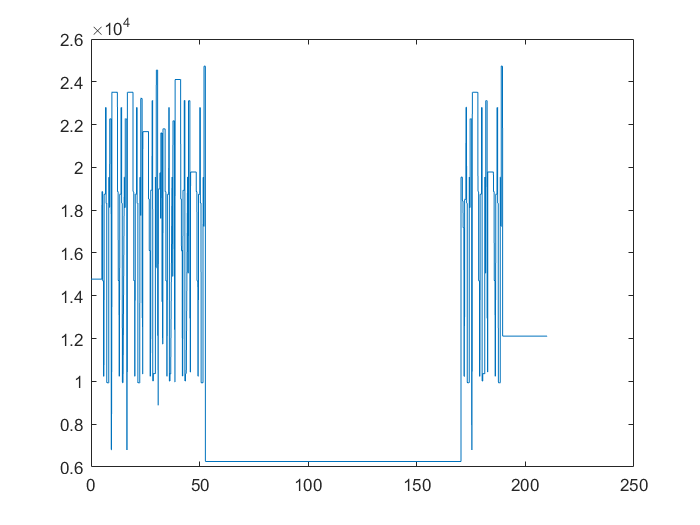

plot(dati_regime(:,1),dati_regime(:,4))

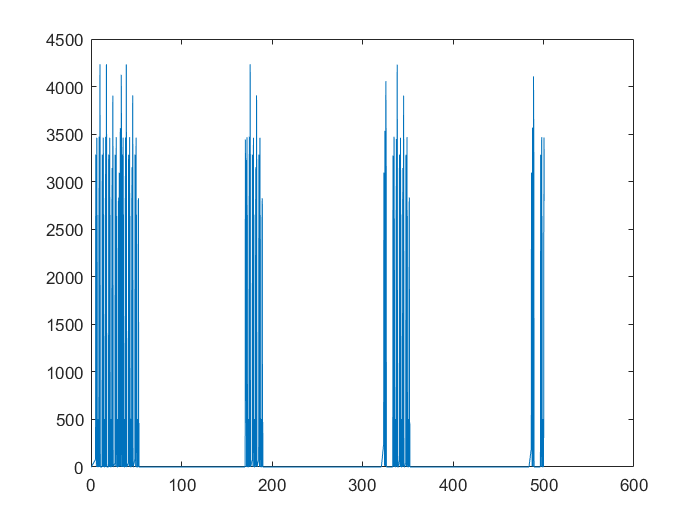

plot(dati_validi_vel(1:end-1,1),v_R1)

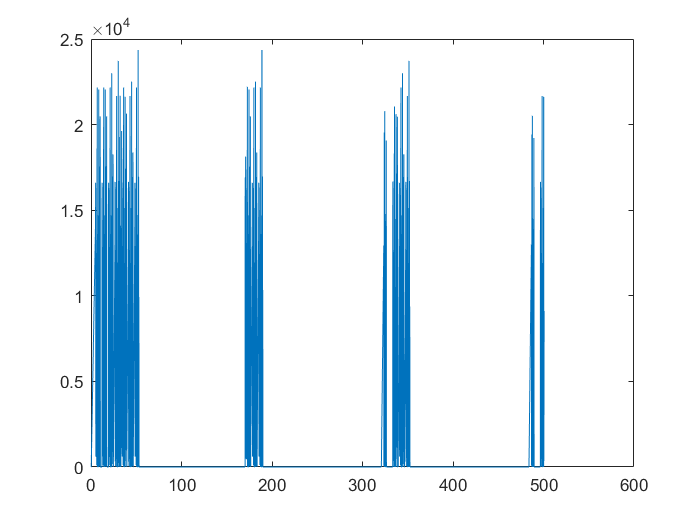

plot(dati_validi_acc(1:end-2,1),abs(a_R1))

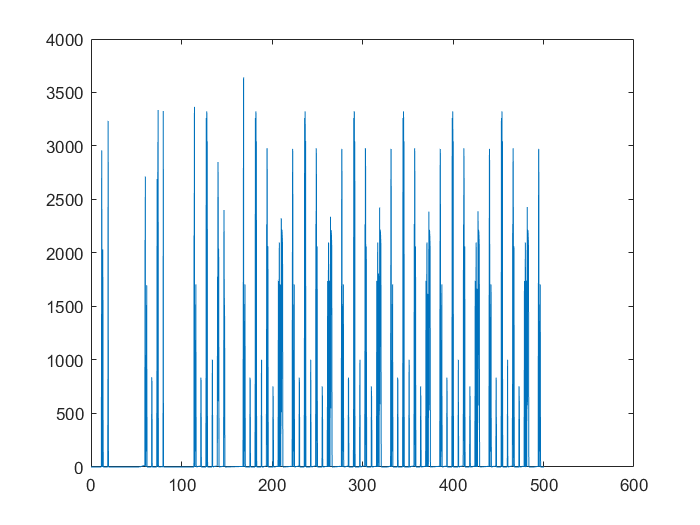

plot(dati_validi_vel_R2(1:end-1,1),v_R2)

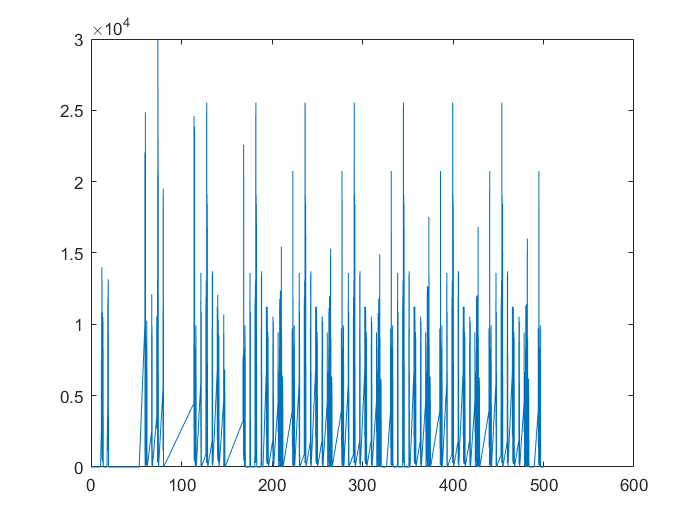

plot(dati_validi_acc_R2(1:end-2,1),abs(a_R2))

# X1

clear all
dati=xlsread("Recording-29.xlsx");

## lavorazione


X_R1=dati(:,5)

X_R1 = 	1.0e+03 *

   -2.9739
   -2.9739
   -2.9739
   -2.9739
   -2.9739
   -2.9739
   -2.9739
   -2.9739
   -2.9739
   -2.9729


Y_R1=dati(:,6)

Y_R1 = 	1.0e+03 *

    1.6660
    1.6660
    1.6660
    1.6660
    1.6660
    1.6660
    1.6660
    1.6660
    1.6660
    1.6698


Z_R1=dati(:,7)

Z_R1 =   845.9443
  845.9443
  845.9443
  845.9443
  845.9443
  845.9443
  845.9443
  845.9443
  845.9443
  844.1125


X_R1=diff(X_R1)

X_R1 =          0
         0
         0
         0
         0
         0
         0
         0
    1.0266
    2.8861


Y_R1=diff(Y_R1)

Y_R1 =          0
         0
         0
         0
         0
         0
         0
         0
    3.7757
   11.3858


Z_R1=diff(Z_R1)

Z_R1 =          0
         0
         0
         0
         0
         0
         0
         0
   -1.8319
   -5.5814


v_R1=sqrt(X_R1.^2 +Y_R1.^2+ Z_R1.^2)./diff(dati(:,1))

v_R1 = 	1.0e+04 *

         0
         0
         0
         0
         0
         0
         0
         0
    0.0180
    0.0542


index_nv=find(v_R1>7000);
dati_validi_vel=dati;

dati_validi_vel(index_nv,:)=[];
v_R1(index_nv)=[];
a_R1=diff(v_R1)./diff(dati_validi_vel(1:end-1,1))

a_R1 = 	1.0e+05 *

         0
         0
         0
         0
         0
         0
         0
    0.0750
    0.1508
    0.1530


index_nv=find(a_R1>68000);
dati_validi_acc=dati_validi_vel;
dati_validi_acc(index_nv,:)=[];
a_R1(index_nv)=[];
index_nv=find(a_R1<-68000);
dati_validi_acc(index_nv,:)=[];
a_R1(index_nv)=[];

X_R2=dati(:,9)

X_R2 = 	1.0e+03 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


Y_R2=dati(:,10)

Y_R2 = 	1.0e+03 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


Z_R2=dati(:,11)

Z_R2 = 	1.0e+03 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


X_R2=diff(X_R2)

X_R2 = 	1.0e+03 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


Y_R2=diff(Y_R2)

Y_R2 = 	1.0e+03 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


Z_R2=diff(Z_R2)

Z_R2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


v_R2=sqrt(X_R2.^2 +Y_R2.^2+ Z_R2.^2)./diff(dati(:,1))

v_R2 = 	1.0e+05 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


index_nv=find(v_R2>7000);
dati_validi_vel_R2=dati;

dati_validi_vel_R2(index_nv,:)=[];
v_R2(index_nv)=[];
a_R2=diff(v_R2)./diff(dati_validi_vel_R2(1:end-1,1))

a_R2 = 	1.0e+04 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


index_nv=find(a_R2>65000);
dati_validi_acc_R2=dati_validi_vel_R2;
dati_validi_acc_R2(index_nv,:)=[];
a_R2(index_nv)=[];

index_fine=find(dati_validi_acc_R2(:,1)>428 );
index_fine=index_fine(1)

index_fine = 6207

index_regime=find(dati_validi_acc_R2(:,1)>210 );
index_regime=index_regime(1)

index_regime = 3176

dati_regime=dati_validi_acc_R2(1:index_regime,:);


## plot

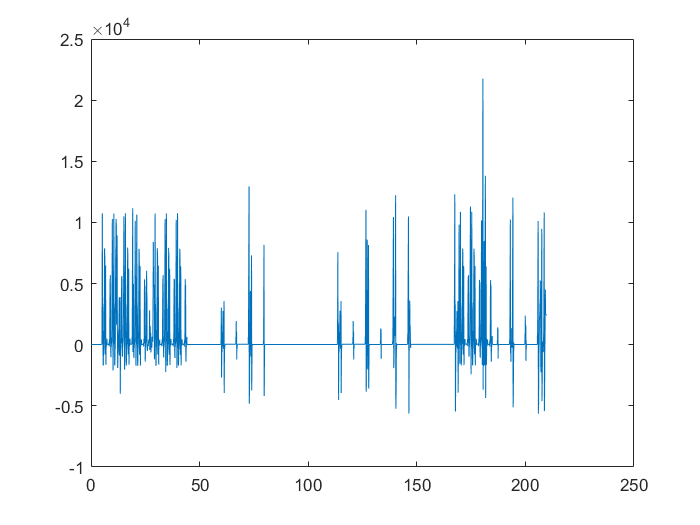

plot(dati_regime(:,1),dati_regime(:,3))

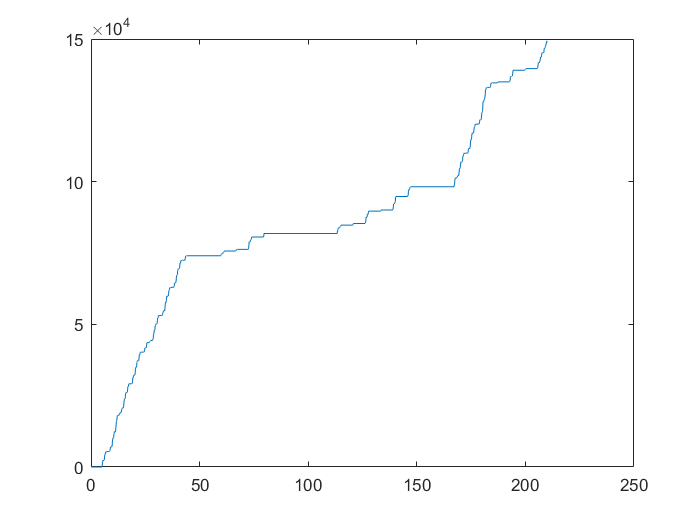

plot(dati_regime(:,1),dati_regime(:,2)-dati_regime(1,2))

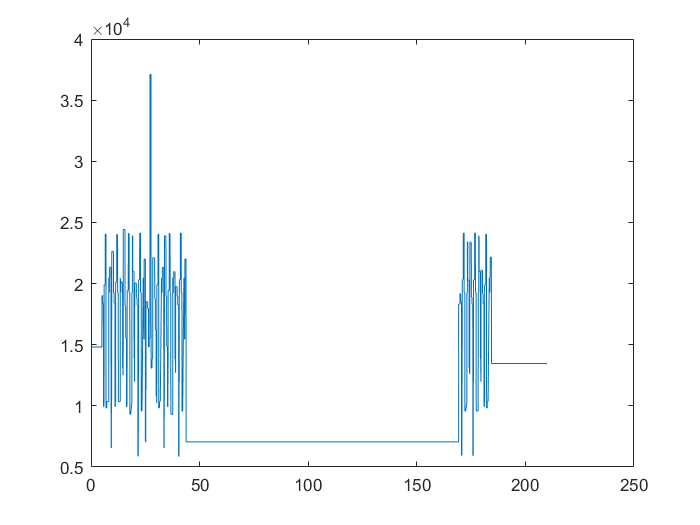

plot(dati_regime(:,1),dati_regime(:,4))

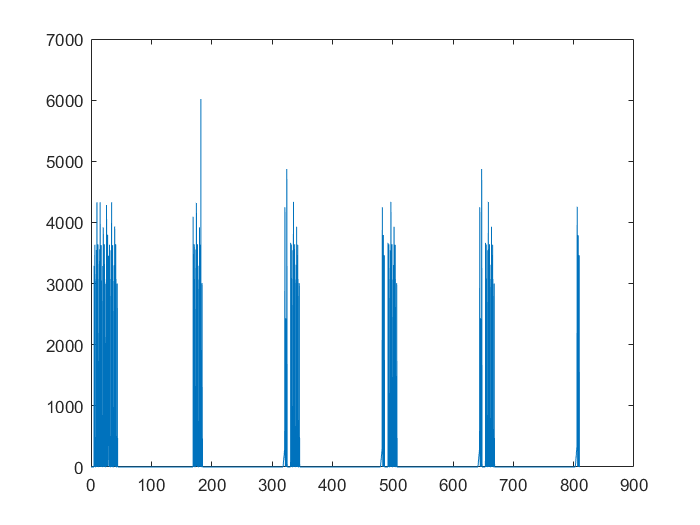

plot(dati_validi_vel(1:end-1,1),v_R1)

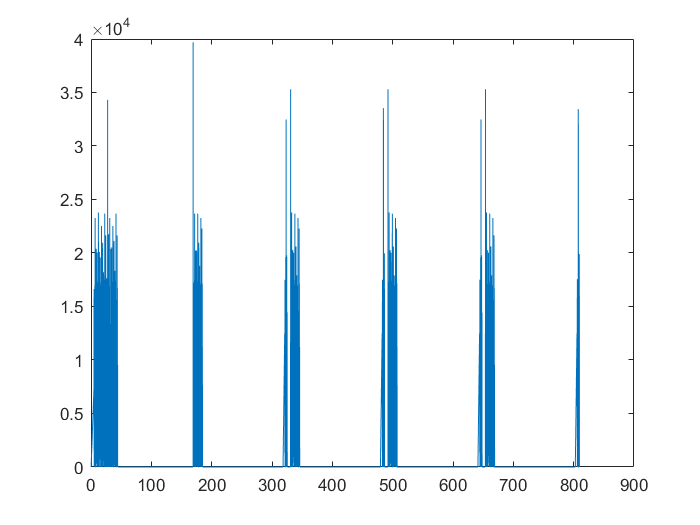

plot(dati_validi_acc(1:end-2,1),abs(a_R1))

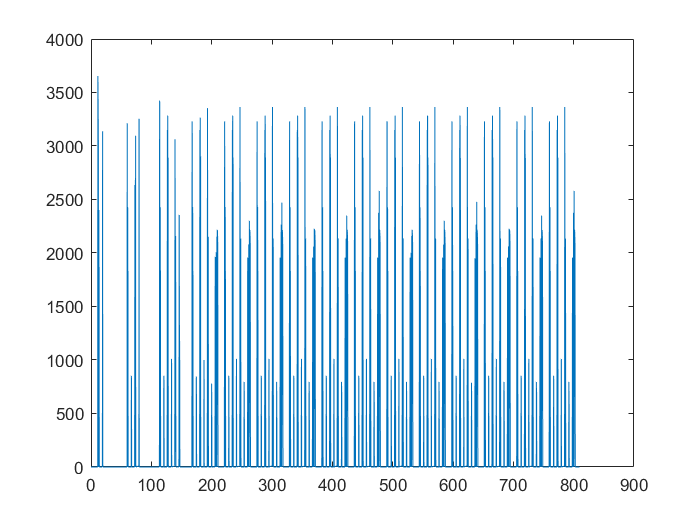

plot(dati_validi_vel_R2(1:end-1,1),v_R2)

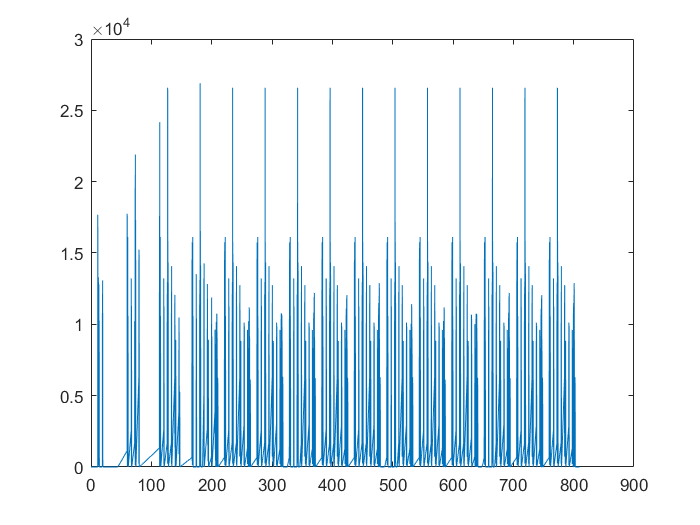

plot(dati_validi_acc_R2(1:end-2,1),abs(a_R2))

# Registrazione Segnali

clear all
dati=xlsread("Recording-34.xlsx");

## lavorazione


X_R1=dati(:,5)

X_R1 = 	1.0e+03 *

         0
         0
         0
   -2.6227
   -2.6164
   -2.6057
   -2.5911
   -2.5735
   -2.5539
   -2.5341


Y_R1=dati(:,6)

Y_R1 = 	1.0e+03 *

         0
         0
         0
    0.6052
    0.6149
    0.6321
    0.6572
    0.6908
    0.7334
    0.7852


Z_R1=dati(:,7)

Z_R1 =          0
         0
         0
  308.7152
  314.7957
  325.4190
  340.5744
  360.2367
  384.3134
  412.4713


X_R1=diff(X_R1)

X_R1 = 	1.0e+03 *

         0
         0
   -2.6227
    0.0063
    0.0107
    0.0146
    0.0176
    0.0195
    0.0198
    0.0181


Y_R1=diff(Y_R1)

Y_R1 =          0
         0
  605.2334
    9.6818
   17.1852
   25.1034
   33.5746
   42.6139
   51.8475
   61.0355


Z_R1=diff(Z_R1)

Z_R1 =          0
         0
  308.7152
    6.0805
   10.6233
   15.1554
   19.6623
   24.0767
   28.1578
   31.8108


v_R1=sqrt(X_R1.^2 +Y_R1.^2+ Z_R1.^2)./diff(dati(:,1))

v_R1 = 	1.0e+05 *

         0
         0
    1.1289
    0.0054
    0.0095
    0.0136
    0.0178
    0.0220
    0.0259
    0.0297


index_nv=find(v_R1>7000);
dati_validi_vel=dati;

dati_validi_vel(index_nv,:)=[];
v_R1(index_nv)=[];
a_R1=diff(v_R1)./diff(dati_validi_vel(1:end-1,1))

a_R1 = 	1.0e+06 *

         0
    0.0113
    0.0170
    0.0172
    0.0173
    0.0173
    0.0165
    0.0155
    0.0146
    0.0074


index_nv=find(a_R1>68000);
dati_validi_acc=dati_validi_vel;
dati_validi_acc(index_nv,:)=[];
a_R1(index_nv)=[];
index_nv=find(a_R1<-68000);
dati_validi_acc(index_nv,:)=[];
a_R1(index_nv)=[];

X_R2=dati(:,9)

X_R2 = 	1.0e+03 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


Y_R2=dati(:,10)

Y_R2 = 	1.0e+03 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


Z_R2=dati(:,11)

Z_R2 = 	1.0e+03 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


X_R2=diff(X_R2)

X_R2 = 	1.0e+03 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


Y_R2=diff(Y_R2)

Y_R2 = 	1.0e+03 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


Z_R2=diff(Z_R2)

Z_R2 = 	1.0e+03 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


v_R2=sqrt(X_R2.^2 +Y_R2.^2+ Z_R2.^2)./diff(dati(:,1))

v_R2 = 	1.0e+04 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


index_nv=find(v_R2>7000);
dati_validi_vel_R2=dati;

dati_validi_vel_R2(index_nv,:)=[];
v_R2(index_nv)=[];
a_R2=diff(v_R2)./diff(dati_validi_vel_R2(1:end-1,1))

a_R2 = 	1.0e+04 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


index_nv=find(a_R2>65000);
dati_validi_acc_R2=dati_validi_vel_R2;
dati_validi_acc_R2(index_nv,:)=[];
a_R2(index_nv)=[];

index_fine=find(dati_validi_acc_R2(:,1)>190);
index_fine=index_fine(1)

index_fine = 2906

index_regime=find(dati_validi_acc_R2(:,1)>167 );
index_regime=index_regime(1)

index_regime = 2221

dati_regime=dati_validi_acc_R2(index_regime:index_fine,:);

index_fine_R1=find(dati_validi_acc(:,1)>190 );
index_fine_R1=index_fine_R1(1)

index_fine_R1 = 2907

index_regime_R1=find(dati_validi_acc(:,1)>167 );
index_regime_R1=index_regime_R1(1)

index_regime_R1 = 2224


index_fine_R1_picco=find(dati_validi_acc(:,1)>333);
index_fine_R1_picco=index_fine_R1_picco(1)

index_fine_R1_picco = 4837

index_regime_R1_picco=find(dati_validi_acc(:,1)>328 );
index_regime_R1_picco=index_regime_R1_picco(1)

index_regime_R1_picco = 4642

## plot

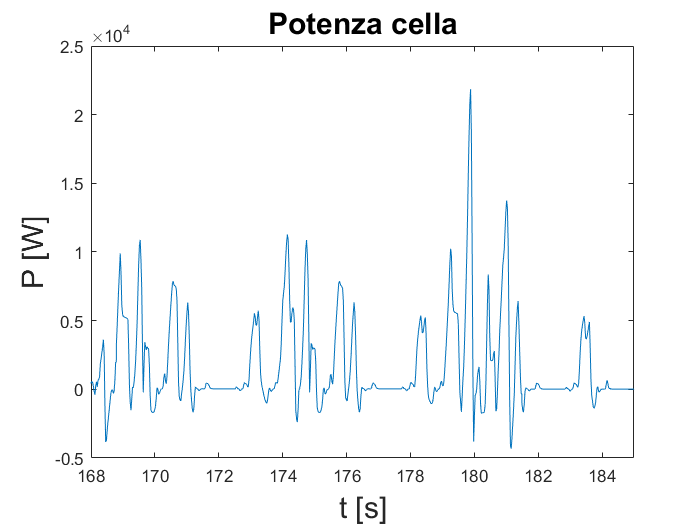

close all
plot(dati_regime(:,1),dati_regime(:,3))
title('Potenza cella',"FontSize",18)
xlabel('t [s]',"FontSize",18)
ylabel('P [W]',"FontSize",18)
xlim([168 185])

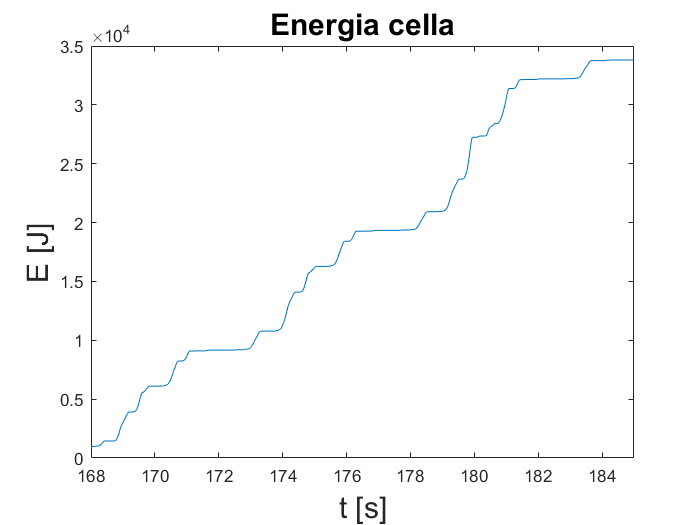

plot(dati_regime(:,1),dati_regime(:,2)-dati_regime(1,2))
title('Energia cella',"FontSize",18)
xlabel('t [s]',"FontSize",18)
ylabel('E [J]',"FontSize",18)
xlim([168 185])

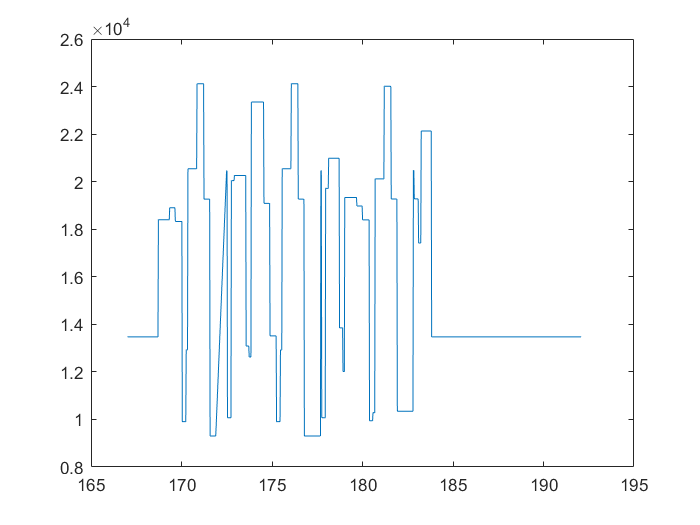

plot(dati_regime(:,1),dati_regime(:,4))

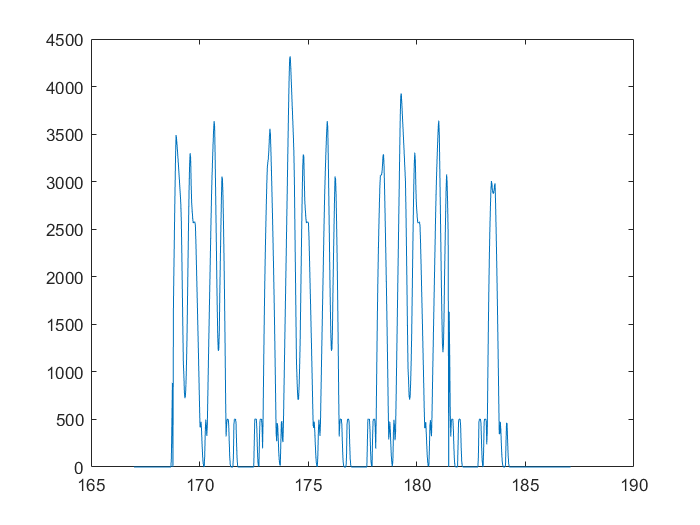

plot(dati_validi_vel(index_regime_R1:index_fine_R1,1),v_R1(index_regime_R1:index_fine_R1))

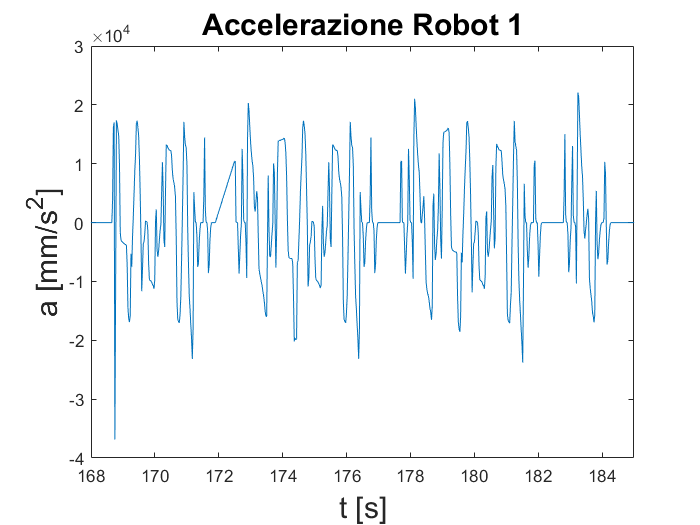

plot(dati_validi_acc(index_regime_R1:index_fine_R1,1),a_R1(index_regime_R1:index_fine_R1))
title('Accelerazione Robot 1',"FontSize",18)
xlabel('t [s]',"FontSize",18)
ylabel('a [mm/s^2]',"FontSize",18)
xlim([168 185])

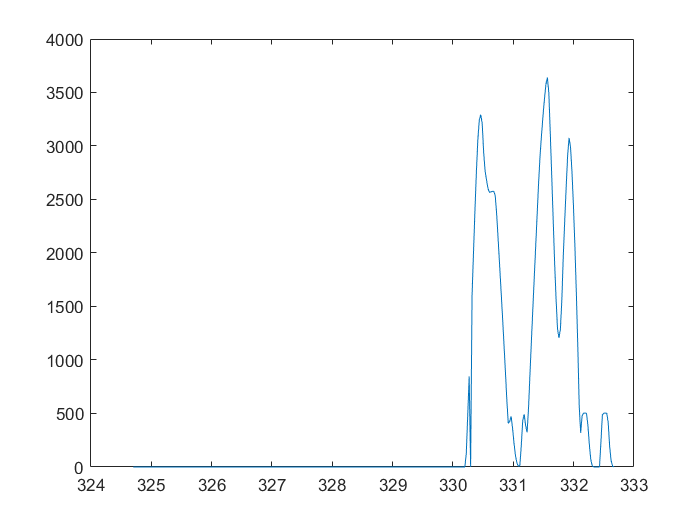

figure()
plot(dati_validi_vel(index_regime_R1_picco:index_fine_R1_picco,1),v_R1(index_regime_R1_picco:index_fine_R1_picco))

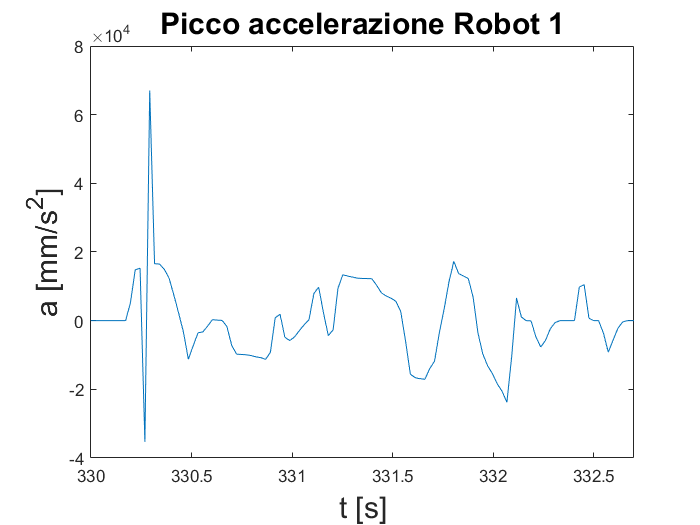

figure()
plot(dati_validi_acc(index_regime_R1_picco:index_fine_R1_picco,1),a_R1(index_regime_R1_picco:index_fine_R1_picco))
title('Picco accelerazione Robot 1',"FontSize",18)
xlabel('t [s]',"FontSize",18)
ylabel('a [mm/s^2]',"FontSize",18)
xlim([330 332.7])

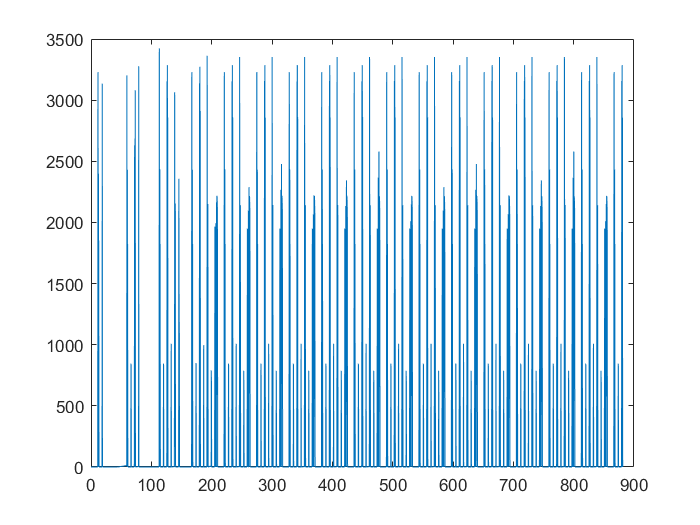

figure()
plot(dati_validi_vel_R2(1:end-1,1),v_R2)

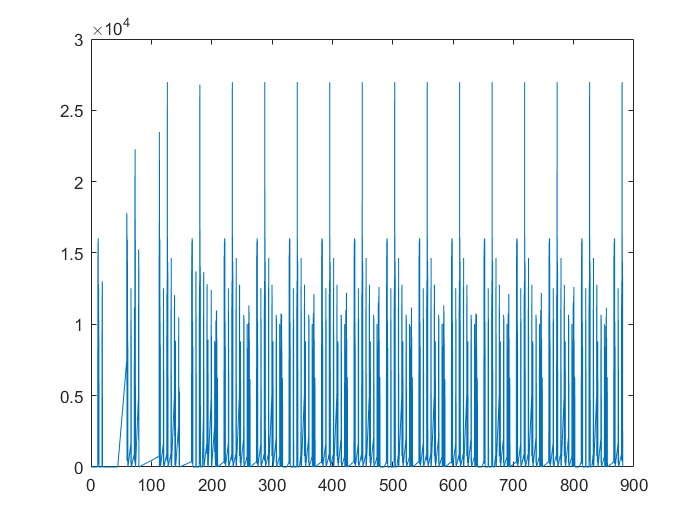

plot(dati_validi_acc_R2(1:end-2,1),abs(a_R2))

## find max

index_a_R1_over=find(a_R1>35000)

index_a_R1_over =         4733
       11977


a_R1(index_a_R1_over)/1000

ans =    67.0290
   67.0290


dati_validi_acc(index_a_R1_over,1)

ans =   330.2920
  814.7800


index_a_R2_over=find(a_R2>35000)


index_a_R2_over =

  0×1 empty double column vector

